format long e

Question - 1

1 (a) 

n=5;
W = Wilkinson(n)

W =      1     0     0     0     1
    -1     1     0     0     1
    -1    -1     1     0     1
    -1    -1    -1     1     1
    -1    -1    -1    -1     1


1(b)

n=2;
H = Hamiltonian(n)

H =     -4.325648115282207e-01     1.253323064748307e-01    -2.292942701362927e+00     2.380079667295102e+00
    -1.665584378238097e+00     2.876764203585488e-01     2.380079667295102e+00    -7.526655318663529e-02
     6.545847228173083e-01    -1.206943486051484e-02     4.325648115282207e-01     1.665584378238097e+00
    -1.206943486051484e-02     1.451581096586605e+00    -1.253323064748307e-01    -2.876764203585488e-01


Question - 2

A = rand(8)

A =      2.010398061147072e-01     6.062687099120523e-01     2.360550732931005e-01     1.442116762372380e-01     2.551015772486168e-01     1.598484578615894e-01     3.553533315960447e-01     7.356173228133357e-01
     8.723539423565155e-01     6.774204157255943e-02     8.204315652625026e-01     7.062857318519447e-01     6.982977156162133e-02     6.722389208297781e-01     5.610817305675267e-01     7.635893576702198e-01
     4.187479305624220e-01     7.968471321759872e-01     2.387031555942687e-01     2.460404668680052e-01     3.649199883393652e-01     4.936771045769120e-01     6.112121717470125e-01     2.323635173736407e-01
     9.561001456034209e-01     7.999252020029955e-02     9.136371477665693e-01     6.885147845163880e-01     6.806010393878338e-01     1.657735115732675e-01     4.991020679354971e-01     3.283245972122641e-01
     3.388137342993913e-01     2.394964606331885e-01     4.678684351723762e-01     9.621453551889536e-01     1.759369614941201e-02     8.192411167880945e-01    

% maximum values in each column
max(A)

vals =      9.561001456034209e-01     7.968471321759872e-01     9.618701665520060e-01     9.621453551889536e-01     6.835938887146491e-01     9.897236392330852e-01     9.556941748112914e-01     7.635893576702198e-01


idxs =      4     3     6     5     8     6     8     2


val =      9.897236392330852e-01


col_idx =      6


% maximum values in each row
max(A, [], 2)

ans =      7.356173228133357e-01
     8.723539423565155e-01
     7.968471321759872e-01
     9.561001456034209e-01
     9.621453551889536e-01
     9.897236392330852e-01
     6.965656341494535e-01
     9.556941748112914e-01



% Max value of overall matrix
max(max(A))

ans =      9.897236392330852e-01



% indices of elements larger than 0.25
[row, col] = find(A>0.25);
cat(2, row, col)

ans =      2     1
     3     1
     4     1
     5     1
     6     1
     7     1
     1     2
     3     2
     6     2
     2     3


Question - 3

A = magic(4)

A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


col_sum = sum(A)

col_sum =     34    34    34    34


row_sum = sum(A,2)

row_sum =     34
    34
    34
    34


diag_sum = sum(diag(A))

diag_sum =     34


A_flipped = flipud(A)

A_flipped =      4    14    15     1
     9     7     6    12
     5    11    10     8
    16     2     3    13


anti_diag_sum = sum(diag(A_flipped))

anti_diag_sum =     34


We can observe that all the values are same here which confirms that the magic() works fine.

Question - 4

4 (a) and (b)

N = [3,4,5];

for n = N
    fprintf('For n = %d\n', n);
    A = magic(n)
    
    s1 = sum(A)
    s2 = sum(A')'
    s3 = sum(diag(A))
    s4 = sum(diag(flipud(A)))
    r = rank(A)
    
    fprintf('After Applying commands of part (b)\n');
    p = randperm(n); q = randperm(n);
    A = A(p,q)
    
    s1 = sum(A)
    s2 = sum(A')'
    s3 = sum(diag(A))
    s4 = sum(diag(flipud(A)))
    r = rank(A)
end

For n = 3


A =      8     1     6
     3     5     7
     4     9     2


s1 =     15    15    15


s2 =     15
    15
    15


s3 =     15


s4 =     15


r =      3


After Applying commands of part (b)


A =      6     8     1
     2     4     9
     7     3     5


s1 =     15    15    15


s2 =     15
    15
    15


s3 =     15


s4 =     12


r =      3


For n = 4


A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


s1 =     34    34    34    34


s2 =     34
    34
    34
    34


s3 =     34


s4 =     34


r =      3


After Applying commands of part (b)


A =      2    16    13     3
     7     9    12     6
    11     5     8    10
    14     4     1    15


s1 =     34    34    34    34


s2 =     34
    34
    34
    34


s3 =     34


s4 =     34


r =      3


For n = 5


A =     17    24     1     8    15
    23     5     7    14    16
     4     6    13    20    22
    10    12    19    21     3
    11    18    25     2     9


s1 =     65    65    65    65    65


s2 =     65
    65
    65
    65
    65


s3 =     65


s4 =     65


r =      5


After Applying commands of part (b)


A =     14    23    16     7     5
     8    17    15     1    24
    20     4    22    13     6
    21    10     3    19    12
     2    11     9    25    18


s1 =     65    65    65    65    65


s2 =     65
    65
    65
    65
    65


s3 =     90


s4 =     40


r =      5


sum(A) prints sum of columns

sum(A')' prints sum of rows

sum(diag(A)) prints sum of diagonal elements of A

sum(diag(flipud(A))) prints sum of anti-diagonal elements of A

rank(A) prints rank of A

We observe that the commands in (b) part change the diagonal and anti-diagonal sum but the row, column sum and rank remains the same. (since it is random, sometimes the diagonal and anti-diagonal sum also turns out to be same)

4 (c)

A = magic(4)

A =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


null(A)

ans =     -2.236067977499790e-01
    -6.708203932499368e-01
     6.708203932499369e-01
     2.236067977499789e-01


null(A, 'r')

ans =     -1
    -3
     3
     1


rref(A)

ans =      1     0     0     1
     0     1     0     3
     0     0     1    -3
     0     0     0     0


Question - 5

n = 3;
A = rand(n)

A =      9.370311262791580e-01     9.596075848708244e-02     7.500985694629042e-02
     3.694341330421954e-01     2.838101650181499e-01     1.860897449149765e-01
     9.808462388301395e-01     1.184423494086178e-01     4.014883929588970e-01



A^(-1)

ans =      1.279989803335785e+00    -4.128417985333389e-01    -4.778775027646361e-02
     4.763377352900013e-01     4.214851948469068e+00    -2.042576482182835e+00
    -3.267570788670020e+00    -2.348327959571261e-01     3.210055421575515e+00



A.^(-1)

ans =      1.067200407707783e+00     1.042092638455555e+01     1.333158121759962e+01
     2.706842466789023e+00     3.523481972310784e+00     5.373751253498117e+00
     1.019527791830762e+00     8.442926073258397e+00     2.490732029960269e+00



1./A

ans =      1.067200407707783e+00     1.042092638455555e+01     1.333158121759962e+01
     2.706842466789023e+00     3.523481972310784e+00     5.373751253498117e+00
     1.019527791830762e+00     8.442926073258397e+00     2.490732029960269e+00


This shows that (a) is false and (b) is true.

Question - 6

n = 4;
p = randn(1,n)

p =     -5.883165430141887e-01     2.183185818197101e+00    -1.363958830865957e-01     1.139313135208096e-01



(length(p)-1:-1:0) .* p

ans =     -1.764949629042566e+00     4.366371636394202e+00    -1.363958830865957e-01                         0


Question - 7

7 (a)

arr1 = -2 * ones(1,16);
arr2 = ones(1,15);
arr3 = ones(1,1);

D = diag(arr1);
D = D + diag(arr2, 1) + diag(arr2, -1);
D = D + diag(arr3, 15) + diag(arr3, -15)

D =     -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0


7 (b)

arr = zeros(1,16);
arr(1) = -2; arr(2) = 1; arr(16) = 1;
D = toeplitz(arr)

D =     -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0


7 (c)

arr = [1,2,3,4,5,6,7,8];
D = triu(toeplitz(arr))

D =      1     2     3     4     5     6     7     8
     0     1     2     3     4     5     6     7
     0     0     1     2     3     4     5     6
     0     0     0     1     2     3     4     5
     0     0     0     0     1     2     3     4
     0     0     0     0     0     1     2     3
     0     0     0     0     0     0     1     2
     0     0     0     0     0     0     0     1


format rat
arr = 1 ./ arr;
D = toeplitz(arr)

D =        1              1/2            1/3            1/4            1/5            1/6            1/7            1/8     
       1/2            1              1/2            1/3            1/4            1/5            1/6            1/7     
       1/3            1/2            1              1/2            1/3            1/4            1/5            1/6     
       1/4            1/3            1/2            1              1/2            1/3            1/4            1/5     
       1/5            1/4            1/3            1/2            1              1/2            1/3            1/4     
       1/6            1/5            1/4            1/3            1/2            1              1/2            1/3     
       1/7            1/6            1/5            1/4            1/3            1/2            1              1/2     
       1/8            1/7            1/6            1/5            1/4            1/3            1/2            1       


Question - 8

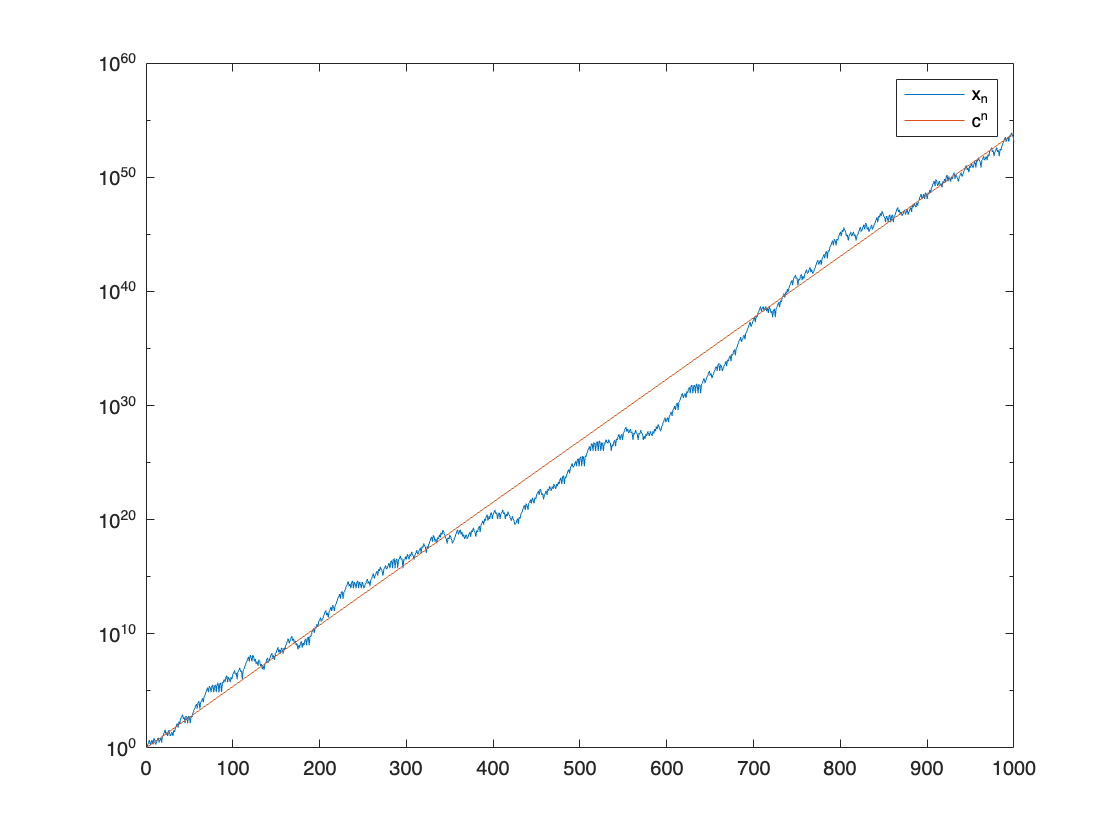

rand('state', 1000);
x = [1, 2];
for n=2:999, x(n+1) = x(n)+sign( rand-0.5)*x(n-1); end

figure;
semilogy (1:1000, abs(x))
c =1.13198824;
hold on
semilogy(1:1000, c.^[1:1000])
legend('x_n', 'c^n');
hold off;

Question - 9

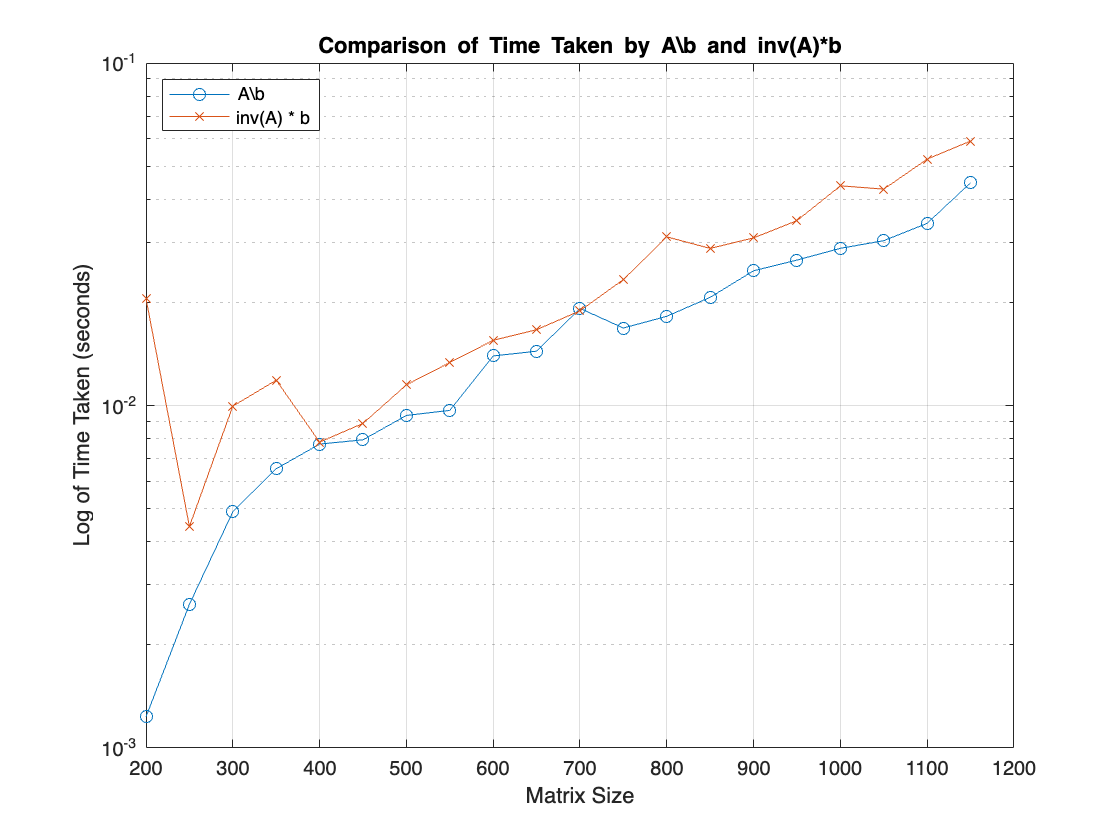

sizes = 200:50:1150;
num_matrices = length(sizes);

time_backslash = zeros(1, num_matrices);
time_inv = zeros(1, num_matrices);

for i = 1:num_matrices
    n = sizes(i);

    A = rand(n);
    b = rand(n, 1);

    tic;
    x_backslash = A\b;
    time_backslash(i) = toc;
    
    tic;
    x_inv = inv(A) * b;
    time_inv(i) = toc;
end

% Plot the results using semilogy to plot log of the time taken
figure;
semilogy(sizes, time_backslash, '-o', 'DisplayName', 'A\\b');
hold on;
semilogy(sizes, time_inv, '-x', 'DisplayName', 'inv(A) * b');
hold off;

title('Comparison of Time Taken by A\\b and inv(A)*b');
xlabel('Matrix Size');
ylabel('Log of Time Taken (seconds)');

legend('Location', 'northwest');
grid on;

Functions

function W = Wilkinson(n)
   W = eye(n);
   W = W - tril(ones(n), -1);
   W(:, end) = ones(n,1);
end

function H = Hamiltonian(n)
   H_11 = randn(n);
   H_22 = -H_11';
   
   H_12 = randn(n);
   H_12 = H_12 + H_12';
   
   H_21 = randn(n);
   H_21 = H_21 + H_21';
   
   H = cat(1, cat(2, H_11, H_12), cat(2, H_21, H_22));
end